# Trabajo de Laboratorio Integrador - Sistemas de Control

Parte A: Modelado y Análisis (Puntos 1 al 4) usando Control System Toolbox

clear; clc; close all;

## 1. Parámetros físicos del circuito (Figura 1)

R1 = 100e3;          % 100 kOhm
C1 = 0.1e-6;         % 0.1 uF
tau1 = R1 * C1;      % Constante de tiempo etapa 1: 0.01 s

R2 = 47e3;           % 47 kOhm
C2 = 0.1e-6;         % 0.1 uF
tau2 = R2 * C2;      % Constante de tiempo etapa 2: 0.0047 s

% Ganancia nominal de la etapa no inversora U2A (R7 = 10k, R9 = 1k)
R7_nom = 10e3;
R9_nom = 1e3;
k_nom  = 1 + R7_nom / R9_nom;  % k = 11

## 2. Puntos 1, 2 y 3: Modelo de transferencia y respuesta al escalón (k = 11)

s = tf('s');

Sys1 = 1 / (tau1 * s + 1);
Sys2 = k_nom / (tau2 * s + 1);

% Lazo abierto G(s) y lazo cerrado con realimentación unitaria Sysf(s)
G_nom    = Sys1 * Sys2;
Sysf_nom = feedback(G_nom, 1);

disp('=== FUNCIÓN DE TRANSFERENCIA EN LAZO CERRADO Sysf(s) (k = 11) ===');

=== FUNCIÓN DE TRANSFERENCIA EN LAZO CERRADO Sysf(s) (k = 11) ===


Sysf_nom

Sysf_nom =               11
  ---------------------------
  4.7e-05 s^2 + 0.0147 s + 12
 
Continuous-time transfer function.


% Frecuencia natural (wn) y amortiguamiento (xi) con damp()
[wn_vec, xi_vec] = damp(Sysf_nom);
wn_nom = wn_vec(1);
xi_nom = xi_vec(1);

% Parámetros de respuesta al escalón con stepinfo() y ganancia DC con dcgain()
info_nom  = stepinfo(Sysf_nom);
y_inf_nom = dcgain(Sysf_nom);
ess_nom   = 1 - y_inf_nom;
Ts_teor   = 4 / (xi_nom * wn_nom);  % Aproximación teórica de envolvente (2%)

% Comprobación de error en estado estacionario (Punto 3) por simulación
% Escalón unitario:
Sys_e_nom = feedback(1, G_nom);
ess_step_sim = dcgain(Sys_e_nom);

% Rampa unitaria (u(t) = t):
t_ramp = linspace(0, 10, 5000)';
y_ramp = lsim(Sysf_nom, t_ramp, t_ramp);
e_ramp = t_ramp - y_ramp;

fprintf('=== PARÁMETROS CASO NOMINAL (k = %.1f) - SIMULACIÓN MATLAB ===\n', k_nom);

=== PARÁMETROS CASO NOMINAL (k = 11.0) - SIMULACIÓN MATLAB ===


fprintf('wn    = %.2f rad/s\n', wn_nom);

wn    = 505.29 rad/s


fprintf('xi    = %.4f\n', xi_nom);

xi    = 0.3095


fprintf('PO    = %.2f %%\n', info_nom.Overshoot);

PO    = 35.95 %


fprintf('Tp    = %.4f s (%.2f ms)\n', info_nom.PeakTime, info_nom.PeakTime*1e3);

Tp    = 0.0065 s (6.48 ms)


fprintf('Ts    = %.4f s (stepinfo exacto) | %.4f s (4/(xi*wn))\n', info_nom.SettlingTime, Ts_teor);

Ts    = 0.0222 s (stepinfo exacto) | 0.0256 s (4/(xi*wn))


fprintf('tr    = %.4f s (10%%-90%%)\n', info_nom.RiseTime);

tr    = 0.0026 s (10%-90%)


fprintf('y(oo) = %.4f V\n', y_inf_nom);

y(oo) = 0.9167 V


fprintf('ess (escalón) = %.4f V (teórico 1/12 = %.4f V)\n', ess_step_sim, 1/12);

ess (escalón) = 0.0833 V (teórico 1/12 = 0.0833 V)


fprintf('ess (rampa)   = diverge a Inf (e(t=10s) = %.4f V, pendiente = %.4f V/s)\n\n', ...
    e_ramp(end), (e_ramp(end)-e_ramp(1))/(t_ramp(end)-t_ramp(1)));

ess (rampa)   = diverge a Inf (e(t=10s) = 0.8345 V, pendiente = 0.0834 V/s)



## 3. Punto 4: Barrido de valores de k con resistencias comerciales E24

k_vals  = [1,   3.2,   5.7,   34];
R7_vals = [0,   2.2e3, 4.7e3, 33e3];
R9_vals = [Inf, 1e3,   1e3,   1e3];

n = length(k_vals);
k_ef      = zeros(n, 1);
wn        = zeros(n, 1);
xi        = zeros(n, 1);
PO        = zeros(n, 1);
Tp        = zeros(n, 1);
Ts_aprox  = zeros(n, 1);
Ts_exacto = zeros(n, 1);
y_inf     = zeros(n, 1);
ess       = zeros(n, 1);

for i = 1:n
    % Ganancia efectiva con los resistores comerciales elegidos
    k_ef(i) = 1 + R7_vals(i) / R9_vals(i);
    
    % Armamos la FT en lazo cerrado para este valor de k
    Sys2_i = k_ef(i) / (tau2 * s + 1);
    Sysf_i = feedback(Sys1 * Sys2_i, 1);
    
    % Extraemos wn, xi, dcgain y métricas con stepinfo
    [wn_i, xi_i] = damp(Sysf_i);
    info_i       = stepinfo(Sysf_i);
    
    wn(i)        = wn_i(1);
    xi(i)        = xi_i(1);
    PO(i)        = info_i.Overshoot;
    Tp(i)        = info_i.PeakTime;
    Ts_aprox(i)  = 4 / (xi(i) * wn(i));
    Ts_exacto(i) = info_i.SettlingTime;
    y_inf(i)     = dcgain(Sysf_i);
    ess(i)       = 1 - y_inf(i);
end

R7_R9_str = ["0 / Inf"; "2.2k / 1k"; "4.7k / 1k"; "33k / 1k"];
Tabla_Punto4 = table(k_vals(:), R7_R9_str, k_ef, round(wn, 2), round(xi, 4), ...
    round(PO, 2), round(Tp, 4), round(Ts_aprox, 4), round(Ts_exacto, 4), ...
    round(y_inf, 4), round(ess, 4), ...
    'VariableNames', {'k', 'R7_R9', 'k_ef', 'wn_rad_s', 'xi', ...
                      'PO_pct', 'Tp_s', 'Ts_teor_s', 'Ts_stepinfo_s', 'y_inf', 'ess'});

disp('=== TABLA PUNTO 4 ===');

=== TABLA PUNTO 4 ===


disp(Tabla_Punto4);

     k        R7_R9       k_ef    wn_rad_s      xi      PO_pct     Tp_s     Ts_teor_s    Ts_stepinfo_s    y_inf      ess  
    ___    ___________    ____    ________    ______    ______    ______    _________    _____________    ______    ______

      1    "0 / Inf"        1      206.28     0.7581     2.59     0.0233     0.0256         0.0274           0.5       0.5
    3.2    "2.2k / 1k"    3.2      298.93     0.5231    14.54     0.0124     0.0256         0.0258        0.7619    0.2381
    5.7    "4.7k / 1k"    5.7      377.56     0.4142    23.94     0.0091     0.0256         0.0223        0.8507    0.1493
     34    "33k / 1k"      34      862.95     0.1812    55.72     0.0038     0.0256         0.0233        0.9714    0.0286



## 4. Punto 5.b: Comparación de Sysf(s) con Simscape para k = 11

script_dir = fileparts(mfilename('fullpath'));
if isempty(script_dir)
    script_dir = pwd;
end
fig_dir = fullfile(script_dir, 'figuras');

out_nom = sim(fullfile(script_dir, 'TP_Lab1_Ideal.slx'));

t_sim = out_nom.simlog.Voltage_Sensor.V.series.time;
y_sim = out_nom.simlog.Voltage_Sensor.V.series.values;

% Grilla temporal uniforme para step() (que requiere paso constante)
t_unif = linspace(0, 0.05, 5000)';
y_teor = step(Sysf_nom, t_unif);

% Interpolamos la salida de Simscape sobre la misma grilla para calcular el error
[t_sim_u, idx_u] = unique(t_sim);
y_sim_interp     = interp1(t_sim_u, y_sim(idx_u), t_unif, 'pchip');
err_max_5b       = max(abs(y_teor - y_sim_interp));

fprintf('\n=== PUNTO 5.b: COMPARACIÓN TEÓRICA VS SIMSCAPE (k = 11) ===\n');


=== PUNTO 5.b: COMPARACIÓN TEÓRICA VS SIMSCAPE (k = 11) ===


fprintf('Error máximo |y_teor(t) - y_sim(t)| = %.4e V\n', err_max_5b);

Error máximo |y_teor(t) - y_sim(t)| = 1.6857e-06 V


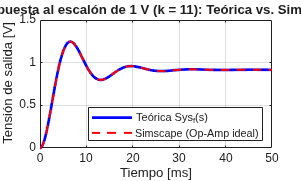


fig5b = figure('Position', [100, 100, 700, 420]);
theme(fig5b, 'light');
plot(t_unif * 1e3, y_teor, 'b-', 'LineWidth', 2, 'DisplayName', 'Teórica Sys_f(s)');
hold on;
plot(t_sim * 1e3, y_sim, 'r--', 'LineWidth', 1.5, 'DisplayName', 'Simscape (Op-Amp ideal)');
grid on;
xlabel('Tiempo [ms]');
ylabel('Tensión de salida [V]');
title('Respuesta al escalón de 1 V (k = 11): Teórica vs. Simscape');
legend('Location', 'southeast');
exportgraphics(fig5b, fullfile(fig_dir, 'punto5b_k11.png'), 'Resolution', 300);

## 5. Punto 5.c: Señal de error e(t) a la salida de U1A (k = 11)

Función de transferencia del error: E(s)/Entrada(s) = 1 / (1 + G(s))

Sys_e = feedback(1, G_nom);

disp('=== FUNCIÓN DE TRANSFERENCIA DEL ERROR E(s)/Entrada(s) (k = 11) ===');

=== FUNCIÓN DE TRANSFERENCIA DEL ERROR E(s)/Entrada(s) (k = 11) ===


Sys_e

Sys_e =   4.7e-05 s^2 + 0.0147 s + 1
  ---------------------------
  4.7e-05 s^2 + 0.0147 s + 12
 
Continuous-time transfer function.


% Tensión de salida de U1A en Simscape y respuesta teórica de Sys_e(s)
e_sim  = out_nom.simlog.U1A.out.v.series.values;
e_teor = step(Sys_e, t_unif);

e_sim_interp = interp1(t_sim_u, e_sim(idx_u), t_unif, 'pchip');
err_max_5c   = max(abs(e_teor - e_sim_interp));

fprintf('=== PUNTO 5.c: SEÑAL DE ERROR EN SALIDA DE U1A (k = 11) ===\n');

=== PUNTO 5.c: SEÑAL DE ERROR EN SALIDA DE U1A (k = 11) ===


fprintf('Valor final teórico e_ss = %.4f V (1/12)\n', dcgain(Sys_e));

Valor final teórico e_ss = 0.0833 V (1/12)


fprintf('Valor final Simscape     = %.4f V\n', e_sim(end));

Valor final Simscape     = 0.0834 V


fprintf('Error máximo |e_teor(t) - e_sim(t)| = %.4e V\n', err_max_5c);

Error máximo |e_teor(t) - e_sim(t)| = 1.6857e-06 V


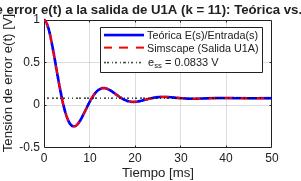


fig5c = figure('Position', [150, 150, 700, 420]);
theme(fig5c, 'light');
plot(t_unif * 1e3, e_teor, 'b-', 'LineWidth', 2, 'DisplayName', 'Teórica E(s)/Entrada(s)');
hold on;
plot(t_sim * 1e3, e_sim, 'r--', 'LineWidth', 1.5, 'DisplayName', 'Simscape (Salida U1A)');
yline(dcgain(Sys_e), 'k:', 'LineWidth', 1.2, 'DisplayName', sprintf('e_{ss} = %.4f V', dcgain(Sys_e)));
grid on;
xlabel('Tiempo [ms]');
ylabel('Tensión de error e(t) [V]');
title('Señal de error e(t) a la salida de U1A (k = 11): Teórica vs. Simscape');
legend('Location', 'northeast');
exportgraphics(fig5c, fullfile(fig_dir, 'punto5c_error_k11.png'), 'Resolution', 300);

## 6. Punto 5.d: Barrido de los 4 valores de k en Simscape

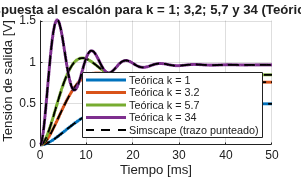

R7_kOhm = [0, 2.2, 4.7, 33];   % R7 en kOhm (R9 = 1 kOhm en el modelo)

PO_sim    = zeros(n, 1);
Tp_sim    = zeros(n, 1);
Ts_sim    = zeros(n, 1);
y_inf_sim = zeros(n, 1);
ess_sim   = zeros(n, 1);
err_max_k = zeros(n, 1);

colores = {'#0072BD', '#D95319', '#77AC30', '#7E2F8E'};
fig5d = figure('Position', [200, 200, 780, 460]);
theme(fig5d, 'light');
hold on;

load_system(fullfile(script_dir, 'TP_Lab1_Ideal.slx'));

for i = 1:n
    % Configuramos R7 para la corrida i sin modificar el archivo .slx
    in_i = Simulink.SimulationInput('TP_Lab1_Ideal');
    in_i = in_i.setBlockParameter('TP_Lab1_Ideal/R7', 'R', num2str(R7_kOhm(i)));
    out_i = sim(in_i);
    
    t_i = out_i.simlog.Voltage_Sensor.V.series.time;
    y_i = out_i.simlog.Voltage_Sensor.V.series.values;
    
    % Respuesta teórica para este k
    Sysf_i   = feedback(Sys1 * (k_ef(i) / (tau2 * s + 1)), 1);
    y_teor_i = step(Sysf_i, t_unif);
    
    % Error máximo entre teórica y Simscape
    [t_iu, idx_iu] = unique(t_i);
    y_i_interp     = interp1(t_iu, y_i(idx_iu), t_unif, 'pchip');
    err_max_k(i)   = max(abs(y_teor_i - y_i_interp));
    
    % Parámetros medidos sobre la curva simulada en Simscape
    y_inf_sim(i) = y_i(end);
    ess_sim(i)   = 1 - y_inf_sim(i);
    info_sim_i   = stepinfo(y_i, t_i, y_inf_sim(i));
    PO_sim(i)    = info_sim_i.Overshoot;
    Tp_sim(i)    = info_sim_i.PeakTime;
    Ts_sim(i)    = info_sim_i.SettlingTime;
    
    % Graficamos teórica (línea continua a color) y Simscape (línea punteada negra)
    plot(t_unif * 1e3, y_teor_i, '-', 'Color', colores{i}, 'LineWidth', 2.2, ...
        'DisplayName', sprintf('Teórica k = %g', k_vals(i)));
    plot(t_i * 1e3, y_i, 'k--', 'LineWidth', 1.4, ...
        'HandleVisibility', 'off');
end

% Agregamos una entrada ficticia en la leyenda para aclarar el trazo punteado
plot(nan, nan, 'k--', 'LineWidth', 1.5, 'DisplayName', 'Simscape (trazo punteado)');
grid on;
xlabel('Tiempo [ms]');
ylabel('Tensión de salida [V]');
title('Punto 5.d: Respuesta al escalón para k = 1; 3,2; 5,7 y 34 (Teórica vs. Simscape)');
legend('Location', 'southeast');
exportgraphics(fig5d, fullfile(fig_dir, 'punto5d_barrido_k.png'), 'Resolution', 300);


Tabla_Punto5d = table(k_vals(:), R7_R9_str, ...
    round(PO, 2), round(PO_sim, 2), ...
    round(Tp, 4), round(Tp_sim, 4), ...
    round(Ts_aprox, 4), round(Ts_exacto, 4), round(Ts_sim, 4), ...
    round(y_inf, 4), round(y_inf_sim, 4), ...
    round(ess, 4), round(ess_sim, 4), ...
    err_max_k, ...
    'VariableNames', {'k', 'R7_R9', 'PO_teor', 'PO_sim', 'Tp_teor', 'Tp_sim', ...
                      'Ts_4_xi_wn', 'Ts_stepinfo', 'Ts_sim', ...
                      'y_inf_teor', 'y_inf_sim', 'ess_teor', 'ess_sim', 'err_max_V'});

disp('=== TABLA PUNTO 5.d (TEÓRICA VS SIMSCAPE) ===');

=== TABLA PUNTO 5.d (TEÓRICA VS SIMSCAPE) ===


disp(Tabla_Punto5d);

     k        R7_R9       PO_teor    PO_sim    Tp_teor    Tp_sim    Ts_4_xi_wn    Ts_stepinfo    Ts_sim    y_inf_teor    y_inf_sim    ess_teor    ess_sim    err_max_V 
    ___    ___________    _______    ______    _______    ______    __________    ___________    ______    __________    _________    ________    _______    __________

      1    "0 / Inf"        2.59      2.65     0.0233     0.0234      0.0256        0.0274       0.0277         0.5       0.4997          0.5     0.5003     6.6347e-08
    3.2    "2.2k / 1k"     14.54     14.59     0.0124     0.0123      0.0256        0.0258       0.0256      0.7619       0.7616       0.2381     0.2384     2.6488e-07
    5.7    "4.7k / 1k"     23.94     23.91     0.0091     0.0091      0.0256        0.0223       0.0223      0.8507       0.8509       0.1493     0.1491     5.9557e-07
     34    "33k / 1k"      55.72     56.04     0.0038     0.0037      0.0256        0.0233       0.0233      0.9714       0.9715       0.0286     0.0285      1

## 7. Punto 6: Circuito con op-amps no ideales (TL081)

load_system(fullfile(script_dir, 'TP_Lab1_TL081.slx'));

% --- Punto 6.a: Comparación Ideal vs TL081 para k = 11 y k = 34 (Escalón 1 V) ---
fprintf('\n=== PUNTO 6.a: COMPARACIÓN IDEAL vs TL081 (RÉGIMEN LINEAL, 1 V) ===\n');


=== PUNTO 6.a: COMPARACIÓN IDEAL vs TL081 (RÉGIMEN LINEAL, 1 V) ===


k_6a      = [11, 34];
R7_6a_kOhm = [10, 33];

fig6a = figure('Position', [220, 220, 780, 440]);
theme(fig6a, 'light');
hold on; grid on;

for i = 1:2
    k_val     = k_6a(i);
    Sysf_curr = feedback(Sys1 * (k_val / (tau2 * s + 1)), 1);
    y_inf_id  = dcgain(Sysf_curr);
    y_id_unif = step(Sysf_curr, t_unif);
    inf_ideal = stepinfo(Sysf_curr);

    simIn_tl = Simulink.SimulationInput('TP_Lab1_TL081');
    simIn_tl = simIn_tl.setBlockParameter('TP_Lab1_TL081/R7', 'R', num2str(R7_6a_kOhm(i)));
    simIn_tl = simIn_tl.setBlockParameter('TP_Lab1_TL081/Step', 'After', '1');
    out_tl   = sim(simIn_tl);

    t_tl     = out_tl.simlog.Voltage_Sensor.V.series.time;
    y_tl     = out_tl.simlog.Voltage_Sensor.V.series.values;
    y_inf_tl = y_tl(end);
    inf_tl   = stepinfo(y_tl, t_tl, y_inf_tl);

    [t_tlu, idx_tlu] = unique(t_tl);
    y_tl_interp      = interp1(t_tlu, y_tl(idx_tlu), t_unif, 'pchip');
    diff_max         = max(abs(y_tl_interp - y_id_unif));

    fprintf('k = %d:\n', k_val);
    fprintf('  Ideal : PO = %.2f%% | Tp = %.4f s | Ts = %.4f s | y(oo) = %.4f V | Peak = %.4f V\n', ...
        inf_ideal.Overshoot, inf_ideal.PeakTime, inf_ideal.SettlingTime, y_inf_id, inf_ideal.Peak);
    fprintf('  TL081 : PO = %.2f%% | Tp = %.4f s | Ts = %.4f s | y(oo) = %.4f V | Peak = %.4f V | DiffMax = %.2f mV\n', ...
        inf_tl.Overshoot, inf_tl.PeakTime, inf_tl.SettlingTime, y_inf_tl, inf_tl.Peak, diff_max*1e3);

    c_line = colores{i};
    plot(t_unif * 1e3, y_id_unif, '-', 'Color', c_line, 'LineWidth', 2, ...
        'DisplayName', sprintf('k = %d - Op-Amp Ideal (PO = %.2f%%)', k_val, inf_ideal.Overshoot));
    plot(t_tl * 1e3, y_tl, 'k--', 'LineWidth', 1.4, ...
        'DisplayName', sprintf('k = %d - TL081 Real (PO = %.2f%%)', k_val, inf_tl.Overshoot));
end

k = 11:


  Ideal : PO = 35.95% | Tp = 0.0065 s | Ts = 0.0222 s | y(oo) = 0.9167 V | Peak = 1.2462 V


  TL081 : PO = 36.00% | Tp = 0.0065 s | Ts = 0.0222 s | y(oo) = 0.9166 V | Peak = 1.2466 V | DiffMax = 0.21 mV


k = 34:


  Ideal : PO = 55.72% | Tp = 0.0038 s | Ts = 0.0233 s | y(oo) = 0.9714 V | Peak = 1.5127 V


  TL081 : PO = 56.19% | Tp = 0.0037 s | Ts = 0.0233 s | y(oo) = 0.9715 V | Peak = 1.5174 V | DiffMax = 1.69 mV


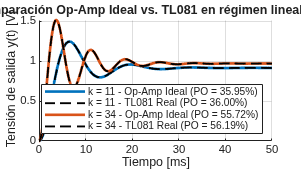

xlabel('Tiempo [ms]'); ylabel('Tensión de salida y(t) [V]');
title('Punto 6.a: Comparación Op-Amp Ideal vs. TL081 en régimen lineal (Escalón de 1 V)');
legend('Location', 'southeast');
exportgraphics(fig6a, fullfile(fig_dir, 'punto6a_comparacion.png'), 'Resolution', 300);


% --- Punto 6.b: Umbral de recorte para k = 34 ---
Sysf_34    = feedback(Sys1 * (34 / (tau2 * s + 1)), 1);
inf_34     = stepinfo(Sysf_34);
V_max_tl   = 8.5;
A_recorte  = V_max_tl / 1.52;
fprintf('\n=== PUNTO 6.b: UMBRAL DE RECORTE (k = 34) ===\n');


=== PUNTO 6.b: UMBRAL DE RECORTE (k = 34) ===


fprintf('Pico por voltio = %.4f V/V (1.52 V/V) | Vmax = %.1f V => A_recorte = %.2f V\n\n', ...
    inf_34.Peak, V_max_tl, A_recorte);

Pico por voltio = 1.5127 V/V (1.52 V/V) | Vmax = 8.5 V => A_recorte = 5.59 V




% --- Punto 6.c: Simulación con TL081 para escalones de 5 V y 7 V (k = 34) ---
fprintf('=== PUNTO 6.c: SATURACIÓN CON ESCALONES DE 5 V y 7 V (k = 34) ===\n');

=== PUNTO 6.c: SATURACIÓN CON ESCALONES DE 5 V y 7 V (k = 34) ===


amps_6c = [5, 7];

fig6c = figure('Position', [240, 240, 780, 450]);
theme(fig6c, 'light');
hold on; grid on;

for i = 1:2
    A_step   = amps_6c(i);
    simIn_sat = Simulink.SimulationInput('TP_Lab1_TL081');
    simIn_sat = simIn_sat.setBlockParameter('TP_Lab1_TL081/R7', 'R', '33');
    simIn_sat = simIn_sat.setBlockParameter('TP_Lab1_TL081/Step', 'After', num2str(A_step));
    out_sat   = sim(simIn_sat);

    t_sat = out_sat.simlog.Voltage_Sensor.V.series.time;
    y_sat = out_sat.simlog.Voltage_Sensor.V.series.values;
    y_lin = A_step * step(Sysf_34, t_unif);

    inf_sat = stepinfo(y_sat, t_sat, y_sat(end));
    fprintf('Escalón %d V -> Pico Simscape TL081 = %.2f V | PO = %.2f%% | Ts = %.4f s | y(oo) = %.4f V\n', ...
        A_step, max(y_sat), inf_sat.Overshoot, inf_sat.SettlingTime, y_sat(end));

    if A_step == 5
        plot(t_unif * 1e3, y_lin, 'b-', 'LineWidth', 2, 'DisplayName', 'Escalón 5 V - Modelo Lineal Sys_f');
        plot(t_sat * 1e3, y_sat, 'k--', 'LineWidth', 1.5, 'DisplayName', 'Escalón 5 V - TL081 (Sin recorte)');
    else
        plot(t_unif * 1e3, y_lin, 'r:', 'LineWidth', 1.8, 'DisplayName', 'Escalón 7 V - Modelo Lineal Sys_f (pico 10,61 V)');
        plot(t_sat * 1e3, y_sat, 'r-', 'LineWidth', 2.2, 'DisplayName', 'Escalón 7 V - TL081 (Recortado en +8,5 V)');
    end
end

Escalón 5 V -> Pico Simscape TL081 = 7.59 V | PO = 56.19% | Ts = 0.0233 s | y(oo) = 4.8574 V
Escalón 7 V -> Pico Simscape TL081 = 8.50 V | PO = 24.94% | Ts = 0.0250 s | y(oo) = 6.8034 V


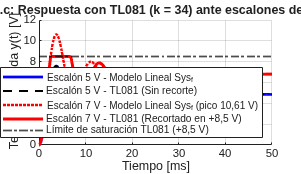

yline(8.5, 'k-.', 'LineWidth', 1.3, 'DisplayName', 'Límite de saturación TL081 (+8,5 V)');
xlabel('Tiempo [ms]'); ylabel('Tensión de salida y(t) [V]');
title('Punto 6.c: Respuesta con TL081 (k = 34) ante escalones de 5 V y 7 V');
legend('Location', 'southeast');
exportgraphics(fig6c, fullfile(fig_dir, 'punto6c_saturacion.png'), 'Resolution', 300);

## 8. Punto 7: Sensibilidad a las tolerancias (+-5% R, +-10% C, k = 11)

fprintf('\n=== PUNTO 7: SENSIBILIDAD A LAS TOLERANCIAS (k = 11) ===\n');


=== PUNTO 7: SENSIBILIDAD A LAS TOLERANCIAS (k = 11) ===



% R en kOhm y C en uF (unidades de los bloques en TP_Lab1_Ideal.slx)
casos_tol = {
    'Mayor sobrepaso (PO máx.)', 0.95*100, 0.90*0.1, 1.05*47, 1.10*0.1, 1.05*10, 0.95*1, '#D95319';
    'Caso nominal (k = 11)',     100,      0.1,      47,      0.1,      10,      1,      '#0072BD';
    'Menor sobrepaso (PO mín.)', 1.05*100, 1.10*0.1, 0.95*47, 0.90*0.1, 0.95*10, 1.05*1, '#77AC30'
};

fig7b = figure('Position', [260, 260, 780, 450]);
theme(fig7b, 'light');
hold on; grid on;

for i = 1:3
    lbl  = casos_tol{i, 1};
    r1_k = casos_tol{i, 2}; c1_u = casos_tol{i, 3};
    r2_k = casos_tol{i, 4}; c2_u = casos_tol{i, 5};
    r7_k = casos_tol{i, 6}; r9_k = casos_tol{i, 7};

    simIn_tol = Simulink.SimulationInput('TP_Lab1_Ideal');
    simIn_tol = simIn_tol.setBlockParameter('TP_Lab1_Ideal/R1', 'R', num2str(r1_k));
    simIn_tol = simIn_tol.setBlockParameter('TP_Lab1_Ideal/C1', 'c', num2str(c1_u));
    simIn_tol = simIn_tol.setBlockParameter('TP_Lab1_Ideal/R2', 'R', num2str(r2_k));
    simIn_tol = simIn_tol.setBlockParameter('TP_Lab1_Ideal/C2', 'c', num2str(c2_u));
    simIn_tol = simIn_tol.setBlockParameter('TP_Lab1_Ideal/R7', 'R', num2str(r7_k));
    simIn_tol = simIn_tol.setBlockParameter('TP_Lab1_Ideal/R9', 'R', num2str(r9_k));
    out_tol   = sim(simIn_tol);

    t_tol   = out_tol.simlog.Voltage_Sensor.V.series.time;
    y_tol   = out_tol.simlog.Voltage_Sensor.V.series.values;
    inf_tol = stepinfo(y_tol, t_tol, y_tol(end));

    fprintf('%-26s -> PO = %.2f%% | Tp = %.4f s | Ts = %.4f s | y(oo) = %.4f V\n', ...
        lbl, inf_tol.Overshoot, inf_tol.PeakTime, inf_tol.SettlingTime, y_tol(end));

    plot(t_tol * 1e3, y_tol, '-', 'Color', casos_tol{i, 8}, 'LineWidth', 2.2, ...
        'DisplayName', sprintf('%s (PO = %.2f%%, T_s = %.2f ms)', lbl, inf_tol.Overshoot, inf_tol.SettlingTime*1e3));
end

Mayor sobrepaso (PO máx.)  -> PO = 39.52% | Tp = 0.0062 s | Ts = 0.0258 s | y(oo) = 0.9229 V
Caso nominal (k = 11)      -> PO = 35.98% | Tp = 0.0065 s | Ts = 0.0222 s | y(oo) = 0.9166 V
Menor sobrepaso (PO mín.)  -> PO = 31.64% | Tp = 0.0069 s | Ts = 0.0226 s | y(oo) = 0.9097 V


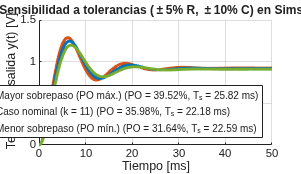

xlabel('Tiempo [ms]'); ylabel('Tensión de salida y(t) [V]');
title('Punto 7.b: Sensibilidad a tolerancias (\pm5% R, \pm10% C) en Simscape (k = 11)');
legend('Location', 'southeast');
exportgraphics(fig7b, fullfile(fig_dir, 'punto7b_tolerancias.png'), 'Resolution', 300);